# 演習4-1　テイラー展開法

（1）指数関数$e^x$のテイラー展開の近似式yをMATLABで計算プログラムを作り，x=1.0，n=10で計算する．

x=1.0;
n=100;
% exp(x)のテイラー展開近似　
y=1.0; % 初期値
% 穴埋め(for loop)
w=y;
for k=1:1:n-1
    w=w*x/k;
    y=y+w;
end
%
% 計算結果はyに
format long
disp(y);

   2.718281828459046




% 以下なら正解
%　2.718281525573192 

（2）x=-1:0.1:1, n=10として，近似値yの値を計算し,横軸x，縦軸yのグラフを作成しなさい．また， MATLABの組込み関数*exp(x)*を使って*z=exp(x)*を計算し，グラフを作成しなさい 

% 近似関数の計算とプロット
% xは行ベクトル
x=-1.0:0.1:1.0;
n=10;
% yはxと同じサイズのベクトルで要素はすべて1
y=ones(size(x));
%
w=y;
% 3行穴埋め(for loop)
for k=1:1;n
    %yはxと同じサイズのベクトルで要素はすべて1
    w=-1/k;
    y=y+w;
end

n =     10


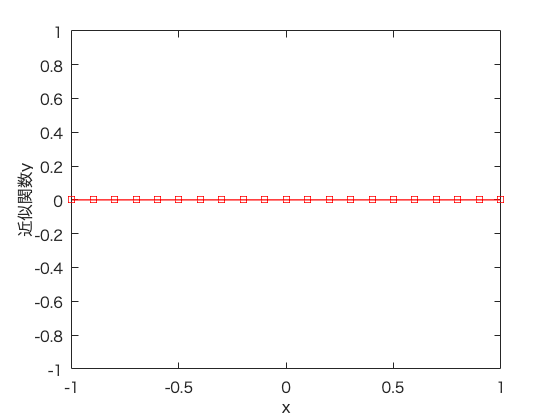

%
% 'r-s'は赤線(red)，実線，四角（square）マークの意味,'LineWidth'は線幅指定
plot(x, y,'r-s','LineWidth',1);
xlabel('x');
ylabel('近似関数y');

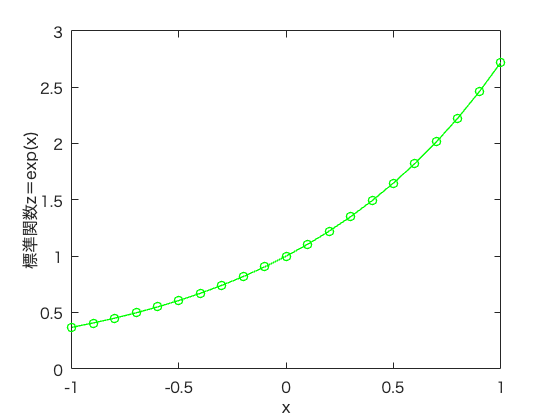

% 標準関数の計算とプロット
z=exp(x);
% 'g--o'は緑線(green)，実線，〇マークの意味
plot(x, z,'g-o','LineWidth',1);
xlabel('x');
ylabel('標準関数z＝exp(x)');

（3） x=-1:0.1:1として，誤差y-zを計算し，横軸x，縦軸y-zのグラフを作成しなさい．

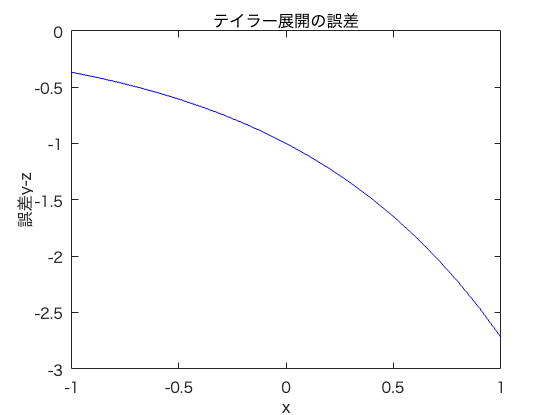

% 1行穴埋め(plot)
plot(x, y-z, 'b');
xlabel('x');
ylabel('誤差y-z');
title('テイラー展開の誤差')

# 演習4-2　cos(x)の近似関数

*cos(x)*のテイラー展開式を使って近似関数*mycos(x,n) *を作りなさい.

注意：　定義する関数*mycos(x,n)*はファイルの最後に記述する．

            もしくは別ファイルmycos.mで定義する．

x=0:.1:2*pi;
figure;
% 1つの図に複数グラフをプロットするためhold on
hold on;
plot(x, mycos(x, 2), 'blue' );

    -1

  -0.500000000000000



plot(x, mycos(x, 4), 'green');

    -1

  -0.500000000000000

  -0.333333333333333

  -0.250000000000000



plot(x, mycos(x, 6), 'cyan');

    -1

  -0.500000000000000

  -0.333333333333333

  -0.250000000000000

  -0.200000000000000

  -0.166666666666667



plot(x, mycos(x, 8), 'magenta');

    -1

  -0.500000000000000

  -0.333333333333333

  -0.250000000000000

  -0.200000000000000

  -0.166666666666667

  -0.142857142857143

  -0.125000000000000



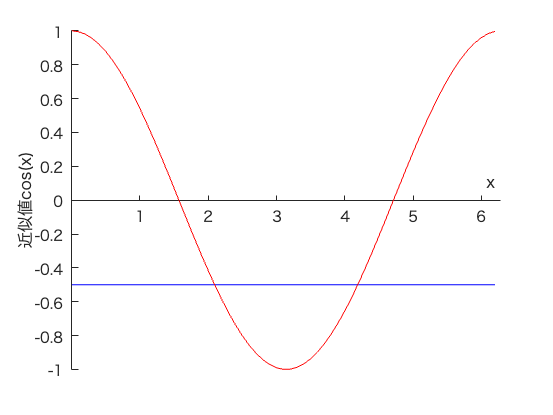

plot(x, cos(x), 'red');
% x軸，y軸のラベル
xlabel('x')
ylabel('近似値cos(x)')
% x軸，y軸の範囲設定
axis([0 2*pi -1 1]);
% x軸の位置を原点に設定
ax=gca;
ax.XAxisLocation = 'origin';
% hold onを解除
hold off;

近似関数*mycos(x,n)　*（注：　ファイルの最後に関数定義を記述）

以下の式を入力xと項数nのfunctionとして記述する


$$y_n=1-\frac{x^2}{2!}+\frac{x^4}{4!}-\dots+(-1)^n\frac{x^{2n}}{2n!}$$


function y=mycos(x,n)
% yはxと同じサイズのベクトルで要素はすべて1
    y=ones(size(x));
% 3行穴埋め(for loop)
    %hold on;
    w=y;
    for k=1:1:n
        w=-w.*(x.*x)/(k*(k-1));
        %w=-1/k;
        disp(w)
        y=y+w;
    end
end